%Demonstration of complicated paths using the NBR
%Fastest lap on record for NBR is 5:19.55 minutes, or 319.55 seconds
%This is set to complete the track in 320 seconds
%POINTS ARE IMPORTED from excel document
%Nurburgring refering to the remenants of the original circuit 'Green Hell'
%Known today as Nordschleife
%NBR is roughly 5km across, control points have been roughly scaled from a
%50x50 grid, giving a 5000x5000 grid which should 'very' roughly
%represent the track in metres
order = 7;

%clear %RUN BEFORE FIRST USE THEN IMPORT COLUMN VECTORS

%Position
%Control Points
%SCALE FACTORS FOR CP2: X = 12.8, Y = -14.2 %Adjust for distance (S:45%)
targx2 = 0.5*targx*(280);
targy2 = targy*(280);
targets = [targx2, targy2]

targets = 1.0e+03 *

    2.7721    3.4143
    3.2535    3.4971
    3.9651    3.5088
    4.8233    3.5325
    5.1163    3.6506
    4.8651    3.8397
    5.0326    3.8987
    5.4302    3.7688
    5.8698    3.8042
    5.9953    3.9342


CP = points(targets, order);
CPx = CP(:,1);
CPy = CP(:,2);
%Curve Parameters
pmin = 0;
pmax = 850;
pstep = 0.1;
%Knot Vector
knot = knotvect(CP, order, pmin, pmax, pstep);
ksz = size(knot);
validpmin = knot(1, order);
validpmax = knot(1, (ksz(1,2)-order+1));
NK2MAT = [];
NK3MAT = [];
NK4MAT = [];
NK5MAT = [];
NK6MAT = [];
NK7MAT = [];
pM1 = [];
pM2 = [];
pM3 = [];
pM4 = [];
pM5 = [];
pM6 = [];
PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
order = 6;
CP = DCP(CP, knot, order);
knot = Dkn(knot);
VelMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
VMagMAT = absBS(VelMAT);
order = 5;
CP = DCP(CP, knot, order);
knot = Dkn(knot);
AccMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
AMagMAT = absBS(AccMAT);
order = 4;
CP = DCP(CP, knot, order);
knot = Dkn(knot);
JerkMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
JMagMAT = absBS(JerkMAT);
order = 3;
CP = DCP(CP, knot, order);
knot = Dkn(knot);
SnapMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
SMagMAT = absBS(SnapMAT);

%Sampling
Sampx = [];
Sampy = [];
tmin = 10;
step1 = round(tmin/pstep);
tmax = 15.2;
step2 = round(tmax/pstep);
for i = step1:1:step2
    Sampx = [Sampx; i*pstep, PosMAT(i,1), VelMAT(i,1), AccMAT(i,1), JerkMAT(i,1), SnapMAT(i,1)];
    Sampy = [Sampy; i*pstep, PosMAT(i,2), VelMAT(i,2), AccMAT(i,2), JerkMAT(i,2), SnapMAT(i,2)];
end
Sampx

Sampx = 1.0e+03 *

    0.0100    2.7779    0.0035    0.0017    0.0006    0.0001
    0.0101    2.7783    0.0037    0.0018    0.0006    0.0001
    0.0102    2.7786    0.0038    0.0018    0.0006    0.0001
    0.0103    2.7790    0.0040    0.0019    0.0006    0.0001
    0.0104    2.7795    0.0042    0.0019    0.0007    0.0001
    0.0105    2.7799    0.0044    0.0020    0.0007    0.0001
    0.0106    2.7803    0.0046    0.0021    0.0007    0.0001
    0.0107    2.7808    0.0048    0.0021    0.0007    0.0001
    0.0108    2.7813    0.0050    0.0022    0.0007    0.0001
    0.0109    2.7818    0.0053    0.0023    0.0007    0.0001


Sampy

Sampy = 1.0e+03 *

    0.0100    3.4153    0.0006    0.0003    0.0001    0.0000
    0.0101    3.4154    0.0006    0.0003    0.0001    0.0000
    0.0102    3.4155    0.0007    0.0003    0.0001    0.0000
    0.0103    3.4155    0.0007    0.0003    0.0001    0.0000
    0.0104    3.4156    0.0007    0.0003    0.0001    0.0000
    0.0105    3.4157    0.0008    0.0003    0.0001    0.0000
    0.0106    3.4158    0.0008    0.0003    0.0001    0.0000
    0.0107    3.4158    0.0008    0.0004    0.0001    0.0000
    0.0108    3.4159    0.0009    0.0004    0.0001    0.0000
    0.0109    3.4160    0.0009    0.0004    0.0001    0.0000


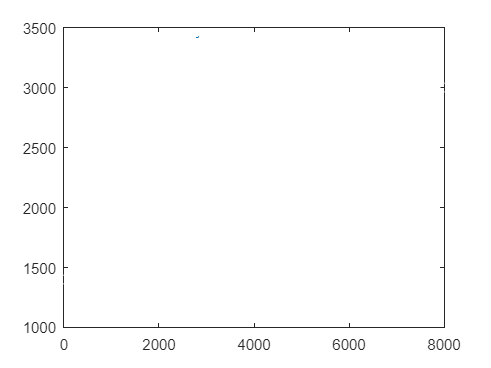


plot(Sampx(:,2), Sampy(:,2))
hold on
scatter([0;8000], [1400;3000], 'white')
hold off

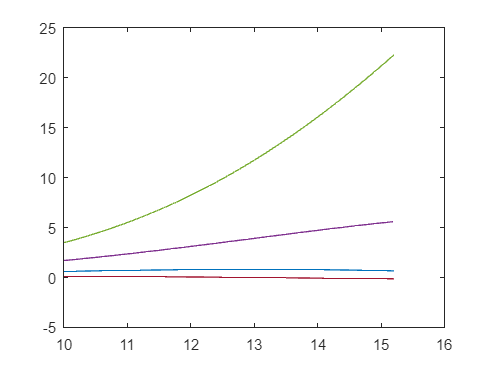

plot(VMagMAT(step1:step2,1)*pstep, VelMAT(step1:step2,1), 'Color', "#77AC30")
hold on
plot(AMagMAT(step1:step2,1)*pstep, AccMAT(step1:step2,1), 'Color', "#7E2F8E")
plot(JMagMAT(step1:step2,1)*pstep, JerkMAT(step1:step2,1), 'Color', "#0072BD")
plot(SMagMAT(step1:step2,1)*pstep, SnapMAT(step1:step2,1), 'Color', "#A2142F")
hold off

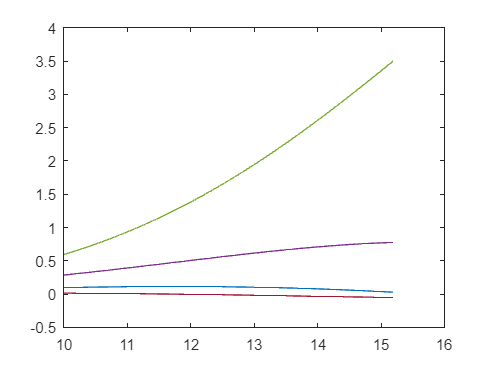

plot(VMagMAT(step1:step2,1)*pstep, VelMAT(step1:step2,2), 'Color', "#77AC30")
hold on
plot(AMagMAT(step1:step2,1)*pstep, AccMAT(step1:step2,2), 'Color', "#7E2F8E")
plot(JMagMAT(step1:step2,1)*pstep, JerkMAT(step1:step2,2), 'Color', "#0072BD")
plot(SMagMAT(step1:step2,1)*pstep, SnapMAT(step1:step2,2), 'Color', "#A2142F")
hold off


dist = 0;
distMAT = [0,0; PosMAT]

distMAT = 1.0e+03 *

         0         0
    2.7721    3.4143
    2.7721    3.4143
    2.7721    3.4143
    2.7721    3.4143
    2.7721    3.4143
    2.7721    3.4143
    2.7721    3.4143
    2.7721    3.4143
    2.7721    3.4143


for i = 1:1:length(PosMAT)
    change = sqrt((distMAT(i+1,1)-distMAT(i,1))^2+(distMAT(i+1,2)-distMAT(i,2))^2);
    dist = dist+change;
end
dist

dist = 2.3003e+04


totV = 0;
for i = 1:1:length(VMagMAT)
    totV = totV+VMagMAT(i,2);
end
dist

dist = 2.3003e+04

distmiles = dist/1609

distmiles = 14.2967

AvV = totV/length(VMagMAT)

AvV = 21.9198

AvVmph = AvV*60^2/1609

AvVmph = 49.0436

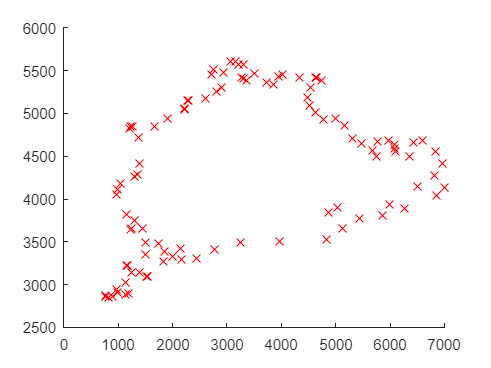



scatter(CPx, CPy, 60, 'red', 'X')

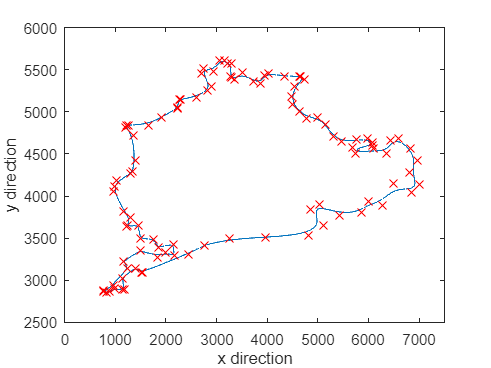

plot(PosMAT(:,1),PosMAT(:,2))
hold on
scatter(CPx, CPy, 60, 'red', 'X')
ylabel('y direction')
xlabel('x direction')
xlim([0,7500])
hold off

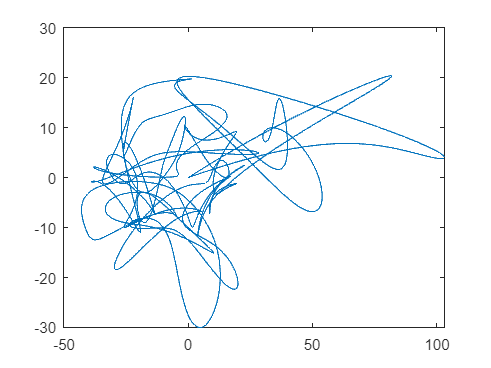

plot(VelMAT(:,1),VelMAT(:,2))

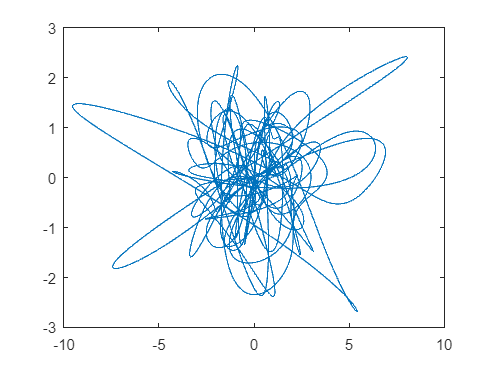

plot(AccMAT(:,1),AccMAT(:,2))

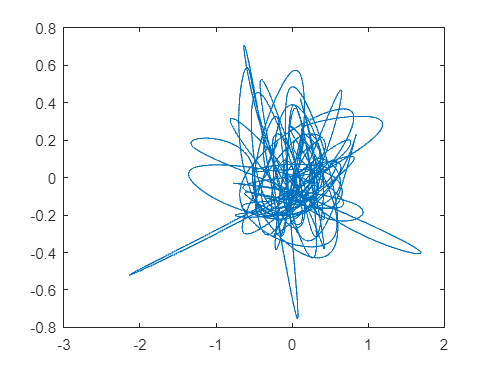

plot(JerkMAT(:,1),JerkMAT(:,2))

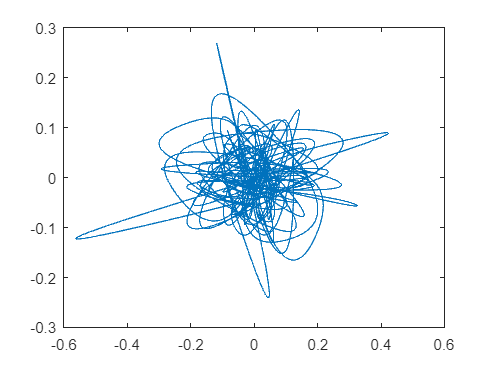

plot(SnapMAT(:,1),SnapMAT(:,2))

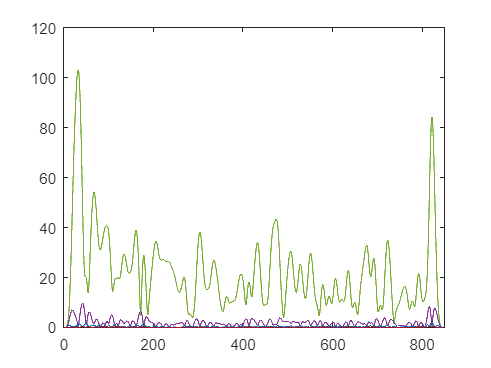


% Magnitudes
plot(VMagMAT(:,1)*pstep, VMagMAT(:,2), 'Color', "#77AC30")
xlim([0, pmax])
hold on
plot(AMagMAT(:,1)*pstep, AMagMAT(:,2), 'Color', "#7E2F8E")
plot(JMagMAT(:,1)*pstep, JMagMAT(:,2), 'Color', "#0072BD")
plot(SMagMAT(:,1)*pstep, SMagMAT(:,2), 'Color', "#A2142F")
hold off

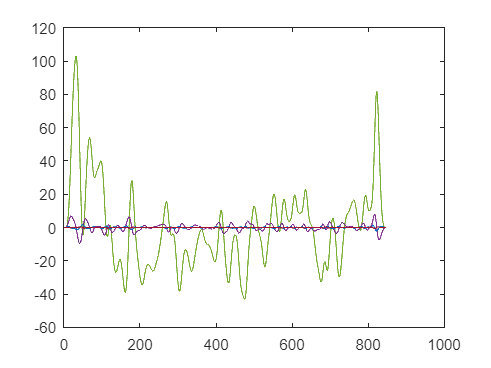


% X Values
plot(VMagMAT(:,1)*pstep, VelMAT(:,1), 'Color', "#77AC30")
hold on
plot(AMagMAT(:,1)*pstep, AccMAT(:,1), 'Color', "#7E2F8E")
plot(JMagMAT(:,1)*pstep, JerkMAT(:,1), 'Color', "#0072BD")
plot(SMagMAT(:,1)*pstep, SnapMAT(:,1), 'Color', "#A2142F")
hold off

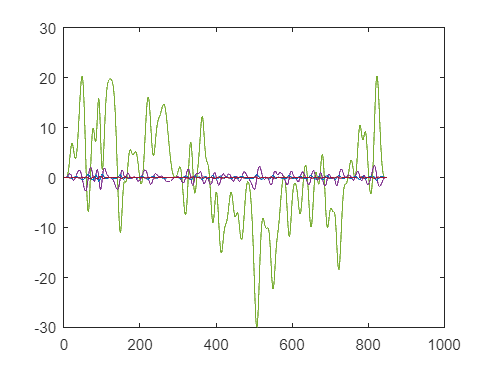


% Y Values
plot(VMagMAT(:,1)*pstep, VelMAT(:,2), 'Color', "#77AC30")
hold on
plot(AMagMAT(:,1)*pstep, AccMAT(:,2), 'Color', "#7E2F8E")
plot(JMagMAT(:,1)*pstep, JerkMAT(:,2), 'Color', "#0072BD")
plot(SMagMAT(:,1)*pstep, SnapMAT(:,2), 'Color', "#A2142F")
hold off

function pMAT = pMAT(p,knot,k)
    N = length(knot);
    pMAT = [];
    for i = 1:1:N-k
        pconst1 = (p-knot(1,i))/(knot(1,i+k-1)-knot(1, i));
        pconst2 = (knot(1,i+k)-p)/(knot(1,i+k)-knot(1,i+1));
        Head = zeros(i-1,1);
        Foot = zeros(N-k-i,1);
        pvect = [Head; pconst1; pconst2; Foot];
        pMAT = [pMAT, pvect];
    end
end
function CP = points(targets, order)
    P = height(targets);
    rep = order - 1;
    CP = [];
    hold = [targets(1,1), targets(1,2)];
    for n = 1:1:rep
        CP = [CP; hold];
    end
    for i = 2:1:P-1
        hold = [targets(i,1), targets(i,2)];
        CP = [CP; hold];
    end
    hold = [targets(P,1), targets(P,2)];
    for k = 1:1:rep
        CP = [CP; hold];
    end
end
function Knot = knotvect(CP, order, pmin, pmax, pstep)
    sz = size(CP);
    P = sz(1,1);
    K = P + order;
    Knot = pmin;
    for i = 1:1:order-1
        Knot = [Knot, pmin+i*pstep];
    end
    for i = 1:1:K-2*order
        Knot = [Knot, i*pmax/(K-2*order+1)];
    end
    for i = 1:1:order
        Knot = [Knot, pmax-(order-i)*pstep];
    end
end
function NK1MAT = NK1MAT(p, knot)
    N = length(knot);
    NK1MAT = [];
    for i = 1:1:N-1
        lowkn = knot(i);
        highkn = knot(i+1);
        if lowkn<=p && p<highkn
            NK1MAT = [NK1MAT, 1];
        else
            NK1MAT = [NK1MAT, 0];
        end
    end
end

function BSplineMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order)
    BSplineMAT = [];
    for p = pmin:pstep:pmax
        if p >= validpmin
            if p<=validpmax
                k = 2;
                NK2MAT = NK1MAT(p, knot)*pMAT(p, knot, k);
                k = 3;
                NK3MAT = NK2MAT*pMAT(p, knot, k);
                k = 4;
                if order < k
                    Pos = NK3MAT*CP;
                else
                    NK4MAT = NK3MAT*pMAT(p, knot, k);
                    k = 5;
                    if order < k
                        Pos = NK4MAT*CP;
                    else
                        NK5MAT = NK4MAT*pMAT(p, knot, k);
                        k = 6;
                        if order < k
                            Pos = NK5MAT*CP;
                        else
                            NK6MAT = NK5MAT*pMAT(p, knot, k);
                            k = 7;
                            if order < k
                                Pos = NK6MAT*CP;
                            else
                                NK7MAT = NK6MAT*pMAT(p, knot, k);
                                Pos = NK7MAT*CP;
                            end
                        end
                    end
                end
                BSplineMAT = [BSplineMAT; Pos];
            end
        end
    end
end

function DP = DCP(CP, knot, k)
    n = length(CP);
    DP = [];
    for i = 1:1:n-1
        I = i+1;
        P1 = [CP(i,1),CP(i,2)];
        P2 = [CP(i+1,1),CP(i+1,2)];
        DPnew = (P2-P1)*k/(knot(I+k)-knot(I));
        DP = [DP; DPnew];
    end
end
function DKnot = Dkn(knot)
    N = length(knot);
    DKnot = [];
    for i = 1:1:N-2
        DKnew = knot(i+1);
        DKnot = [DKnot, DKnew];
    end
end
function MagMAT = absBS(Pos)
    N = length(Pos.');
    MagMAT = [];
    for i = 1:1:N
        X = Pos(i,1);
        Y = Pos(i,2);
        abs = sqrt(X^2+Y^2);
        MagMAT = [MagMAT; i, abs];
    end
end